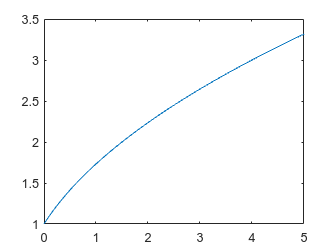

clc;clear

h = 0.01; % step
T = 5; %simultion time
x = 1; % init value
y = 1; % 
t = 0; % time valuable
for i = 1: T/h
    K1 = func(t(i), x);
    K2 = func(t(i) + h/2, x + K1 * h/2);
    k3 = func(t(i) + h/2, x + K2 * h/2);
    k4 = func(t(i) + h, x + k3 *h);
    x = x + h/6 * (K1 + 2*K2 + 2*k3 + k4);
    y = [y, x];
    t(i + 1) = t(i) + h;
end
plot(t, y)

function y_ret = func(t, x_k)
    y_ret = x_k - 2*t/x_k;
end